# **Controllo di una cartiera**

Si consideri un macchinario per la produzione di carta, anche detto cartiera. Lo schema a blocchi ne scompone il funzionamento in tre parti.

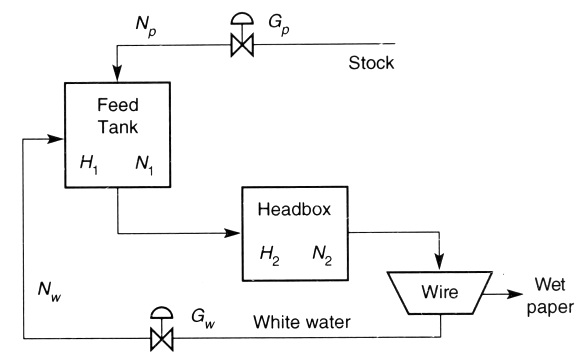

La prima fase del processo prevede che tutti gli ingredienti per la produzione della carta vengano mischiati assieme. Gli ingressi alla vasca di alimentazione sono, in particolare, l'acqua e la cellulosa (opportunamente dosate attraverso le corrispettive valvole). La soluzione così ottenuta viene fornita in ingresso alla testata per la seconda fase del processo, durante la quale inizia la separazione tra la carta ed i liquidi.

Al termine della separazione la carta ancora inumidita viene compressa e restituita in uscita verso un ulteriore processo di essiccatura.

La soluzione composta da acqua e sostanze chimiche per la sbiancatura della carta viene riportata in ingresso alla vasca di alimentazione in modo tale da riciclarla. Si tratta di un'operazione necessaria in quanto il processo di produzione della carta spreca molte risorse.

## Modellazione del sistema

L'intero processo di produzione della carta può essere visto come un processo non lineare caratterizzato da tre uscite, due ingressi manipolabili e due ingressi di disturbo dei quali uno di essi è misurato. Gli stati del processo sono:

- $H_1$ livello del liquido nella vasca di alimentazione

- $H_2$ livello del fluido nella testata

- $N_1$ densità del liquido nella vasca di alimentazione

- $N_2$ la densità del fluido nella testata

L'obiettivo primario del controllo è quello di mantenere le variabili di processo $H_2$ ed $N_2$ ad un valore predeterminato (setpoint), attraverso la regolazione delle variabili manipolabili rappresentate da:

- $G_p$ portata del materiale fornito in ingresso alla vasca di alimentazione

- $G_w$ portata dell'acqua riciclata con sostanze sbiancanti

La densità del materiale fornito in ingresso alla vasca di alimentazione $N_p$ rappresenta un disturbo misurabile mentre la densità dell'acqua riciclata con sostanze sbiancanti $N_w$ rappresenta un disturbo non misurabile.

### Rappresentazione nello spazio di stato

Linearizzando opportunamente, si ottiene un modssello lineare tempo continuo caratterizzato nello spazio di stato dalle seguenti matrici:


$$A=\left\lbrack \begin{array}{cccc}
-1\ldotp 930 & 0 & 0 & 0\\
0\ldotp 394 & -0\ldotp 426 & 0 & 0\\
0 & 0 & -0\ldotp 630 & 0\\
0\ldotp 820 & -0\ldotp 784 & 0\ldotp 413 & -0\ldotp 426
\end{array}\right\rbrack ,\;\;\;\;\;B=\left\lbrack \begin{array}{cccc}
1\ldotp 274 & 1\ldotp 274 & 0 & 0\\
0 & 0 & 0 & 0\\
1\ldotp 340 & -0\ldotp 650 & 0\ldotp 203 & 0\ldotp 406\\
0 & 0 & 0 & 0
\end{array}\right\rbrack ,\;\;\;\;\;C=\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack ,\;\;\;\;\;D=\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


## Richiesta 1

Implementa una rappresentazione nello spazio di stato per il plant. Definisci i nomi degli input e degli ouput. Esamina la risposta in anello aperto a seguito dell'applicazione di un impulso e di un gradino, rispettivamente. Cosa è possibile affermare sul sistema?

% Operazioni preliminari
close all;
clear all; 
clc;

### Matrici del sistema

% Matrici del sistema linearizzato
A = [-1.930,      0,      0,      0;
      0.394, -0.426,      0,      0;
          0,      0, -0.630,      0;
      0.820, -0.784,  0.413, -0.426];

B = [1.274,  1.274,     0,     0;
         0,      0,     0,     0;
     1.340, -0.650, 0.203, 0.406;
         0,      0,     0,     0];

C = [0, 1, 0, 0;
     0, 0, 1, 0;
     0, 0, 0, 1];

D = zeros(3,4);

### Definizione del sistema

% Sistema nello spazio di stato
sys = ss(A,B,C,D);

% Definizione dell'unità di tempo
sys.TimeUnit = 'minutes';

% Definizione degli input
sys.InputName = {'G_p','G_w','N_p','N_w'};

% Definizione degli ouput
sys.OutputName = {'H_2','N_1','N_2'};

### Analisi del sistema

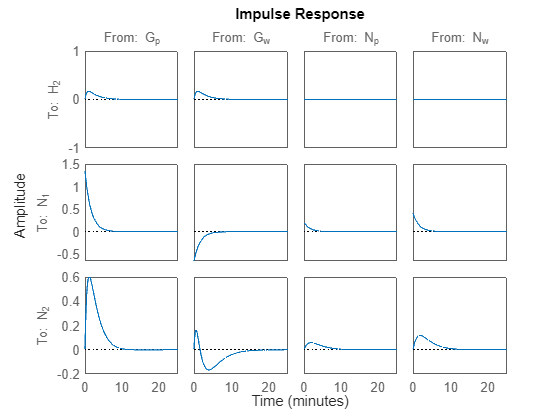

% Risposta all'impulso in anello aperto
impulse(sys);

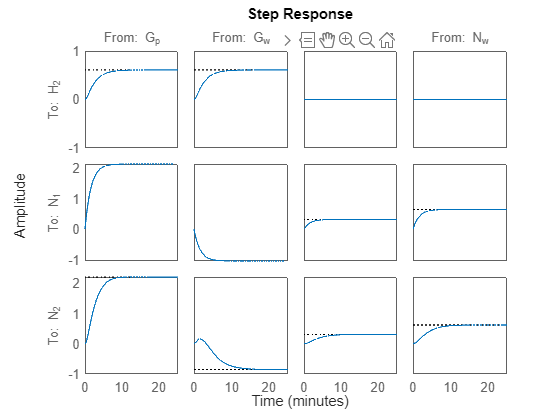


% Risposta al gradino in anello aperto
step(sys);

Sia la risposta all'impuslo che la risposta al gradino mostrano come il sistema sia stabile. Nel primo caso, a seguito di una sollecitazione, il sistema si riporta nello stato di partenza. Nel secondo caso, il sistema insegue il riferimento, tranne in alcuni casi ove il riferimento non ha alcun effetto sulla corrispettiva uscita. Poiché il sistema è composto da 3 uscite, ciascuna delle quali dipende da 4 input (motivo per cui le rappresentazioni sono 12), l'unico modo per poter controllare il sistema è quello di utilizzare un controllore MPC.

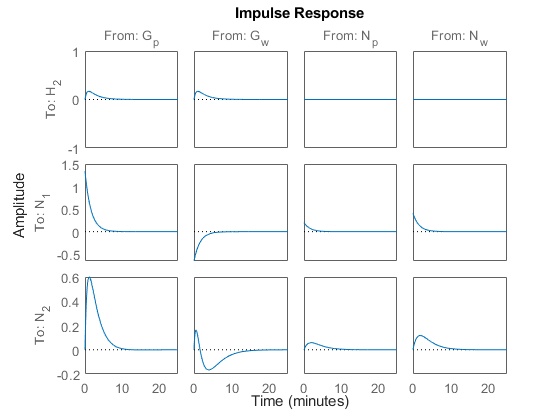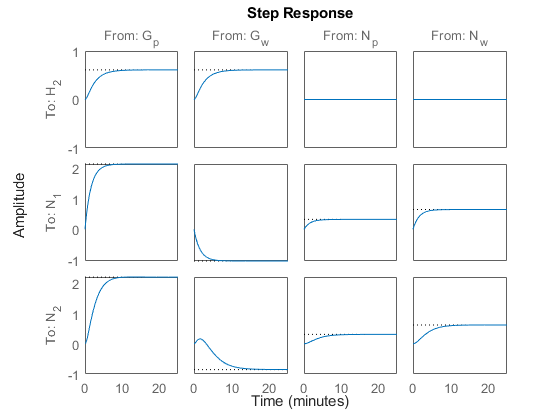

## Richiesta 2

Il sistema presenta una dinamica la cui entità è nell'ordine dei minuti. Supponi che i requisiti di progettazione includano un tempo di risposta di almeno 10 minuti. Quale potrebbe essere un valore appropriato di $T_s$? Conseguentemente, quali potrebbero essere i valori di $H_p$ ed $H_c$?

### Scelta del periodo di campionamento

Usualmente si desidera un periodo di campionamento che sia compreso tra il 10% ed il 25% del tempo di risposta.

Dalla risposta al gradino del sistema in anello aperto, si evince che ciascuna uscita raggiunge il suo valore finale in meno di 10 minuti. Conseguentemente, un periodo di campionamento di 1 minuto (10% del tempo di risposta desiderato) è una scelta ragionevole; se il sistema fosse stato più lento, al contrario, sarebbe stato più opportuno scegliere un periodo di campionamento di 2 minuti.

% Periodo di campionamento [min]
Ts = 1;

### Scelta dell'orizzonte di predizione

Noti il periodo di campionamento ed il tempo di risposta, un valore congruo dell'orizzonte di predizione può essere ottenuto dalla relazione:


$$t_r \approx T_s \cdot H_p \;\;\;\Rightarrow \;\;H_p =\frac{t_r }{T_s }=\frac{10}{1}=10$$


% Orizzonte di predizione
Hp = 10;

### Scelta dell'orizzonte di controllo

L'orizzonte di controllo deve essere molto più piccolo dell'orizzonte di predizione, per esempio è possibile sceglierlo uguale a 2.

% Orizzonte di controllo
Hc = 2;

## Richiesta 3

Utilizzando il tool MPC Designer, inizializza il controllore MPC con i parametri identificati al punto precedente ed osserva la simulazione iniziale. Cosa è possibile affermare?

### Inizializzazione del controllore

Una volta importato il sistema e stabilito il periodo di campionamento è necessario differenziare tra gli ingressi manipolabili ($G_p$ e $G_w$), gli ingressi di disturbo misurabili ($N_p$) e gli ingressi di disturbo non misurabili ($N_w$). Le uscite sono invece tutte misurabili ($H_2$, $N_1$, $N_2$).

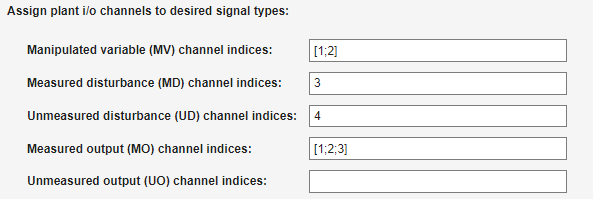

### Analisi della simulazione

Ancora una volta, si osserva la ripartizione tra ingressi ed uscite. In particolare, solo i primi due ingressi presentano un andamento diverso da zero perché gli unici a poter essere manipolati dal controllore (gli ultimi due ingressi sono invece dei disturbi).

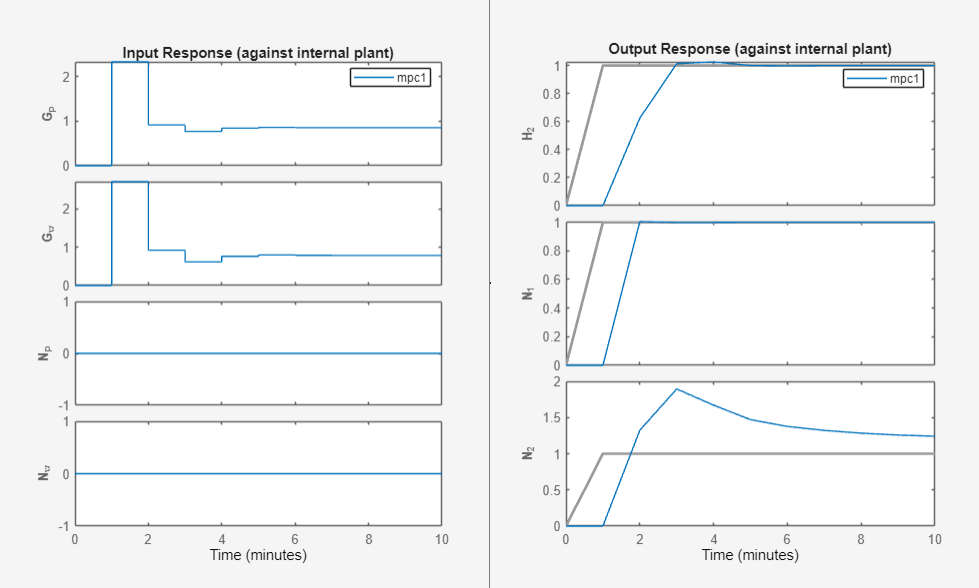

Le prime due uscite presentano un inseguimento soddisfacente del riferimento, mentre la terza uscita presenta un overshoot ed un errore a regime non indifferente che, data la pendenza della curva, non diminuisce pur andando ad aumentare l'intervallo di osservazione.

## Richiesta 4

Con riferimento agli ingressi, le variabili manipolabili ($G_p$ e $G_w$) sono espresse in kg/ore mentre le variabili di disturbo ($N_p$ e $N_w$) sono espresse in percentuale. Con riferimento alle uscite, la prima ($N_2$) è espressa in metri e le restanti ($N_1$ e $N_2$) sono espresse in percentuale. Imposto che $\left|G_p \right|\le 10$ e che $\left|G_w \right|\le 10$, cosa accade alla risposta del sistema? I vincoli vengono soddisfatti?

### Scelta delle unità di misura

Dalla sezione I/O Attributes si specificano le unità di misura per ciascun input e output. In questo modo, i corrispettivi andamenti presenteranno entrambi gli assi opportunamente graduati.

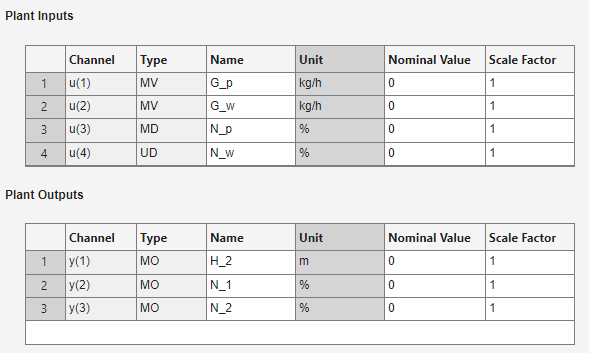

### Definizione dei vincoli sugli ingressi

Poiché entrambi gli ingressi manipolabili ($G_p$ e $G_w$) sono già limitati nell'intervallo desiderato, è ragionevole aspettarsi che non vi sia alcun effetto a seguito dell'imposizione dei vincoli sugli ingressi compilando le corrispettive voci della sezione Constraints.

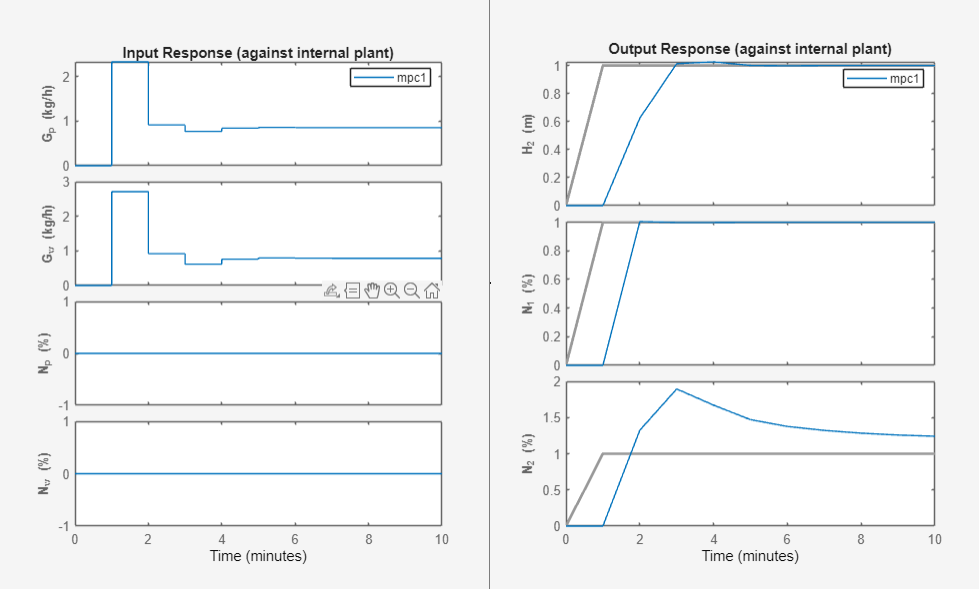

Come predetto, non è possibile apprezzare alcun cambiamento nella risposta in quanto il vincolo era già abbondantemente soddisfatto.

## Richiesta 5

Si vuole adesso che il sistema presenti un'azione di controllo che non sia molto aggressiva. Come dovrebbero essere impostati i pesi?

### Scelta dei pesi sulle uscite

Da quanto richiesto dal problema, si vogliono mantenere le variabili di processo $H_2$ ed $N_2$ ad un valore predeterminato, ma non vi è alcuna specifica sulla variabile di processo $N_1$. Si può allora pensare di pesare opportunamente $H_2$ ed $N_2$ andando invece a penalizzare $N_1$.

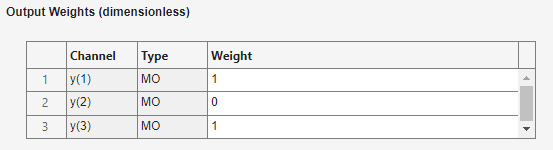

La modifica dei pesi migliora l'andamento della terza uscita che, pur mantenendo l'overshoot, adesso presenta un errore nullo a regime.

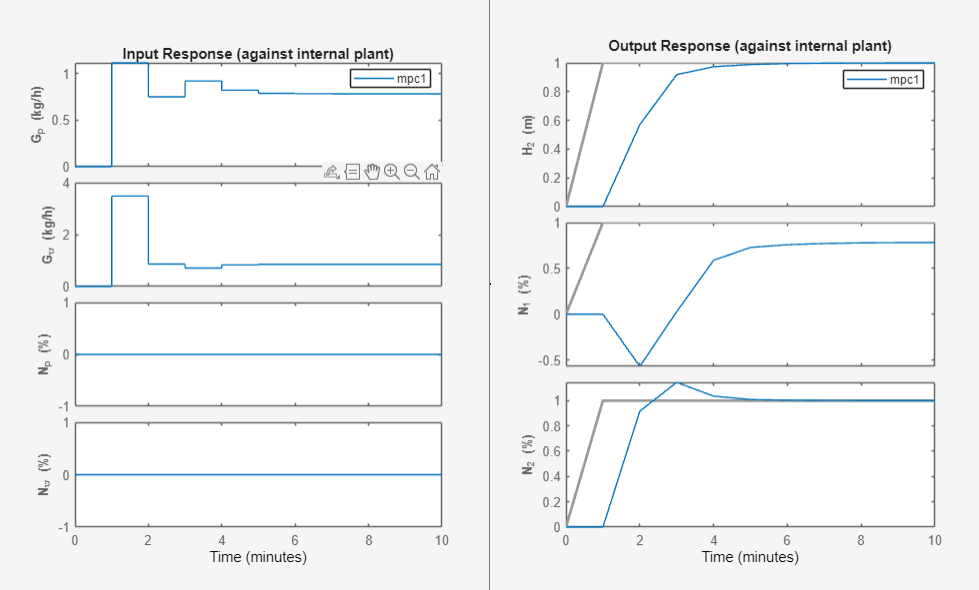

### Scelta dei pesi sugli ingressi

Per migliorare ulteriormente l'azione di controllo e fare in modo che questa non sia molto aggressiva, è possibile agire sui pesi dei rate degli ingressi manipolabili ($G_p$ e $G_w$), cioè delle loro variazioni. L'evoluzione di questi due ingressi mostra infatti un picco iniziale importante, che se pesato opportunamente (andando a dare più importanza) potrebbe migliorare le prestazioni dell'intero sistema.

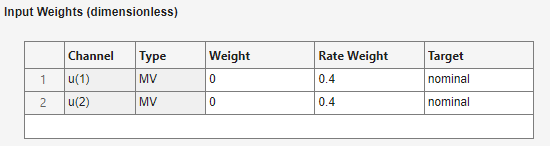

La modifica dei pesi restituisce un risultato che è sicuramente meno aggressivo, con degli ingressi più contenuti e delle uscite più lente.

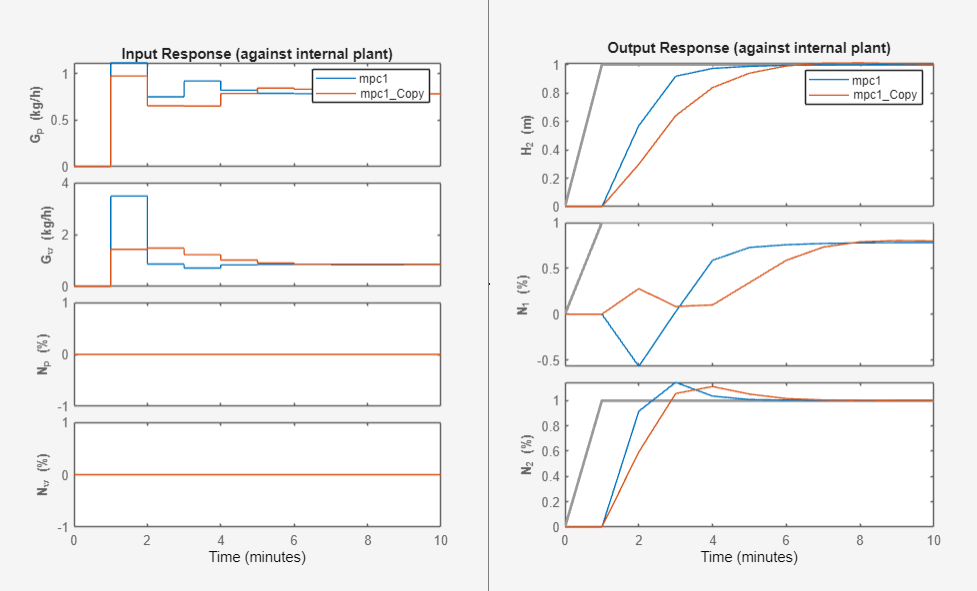

Un'azione di controllo ancor meno aggressiva può essere ottenuta andando a ridurre il peso sulle uscite $H_2$ ed $N_2$.

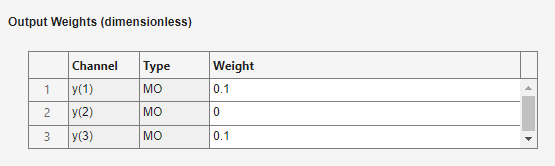

Confrontando i diversi andamenti si osserva come l'ultimo ottenuto sia quello meno aggressivo e, conseguentemente, meno reattivo.

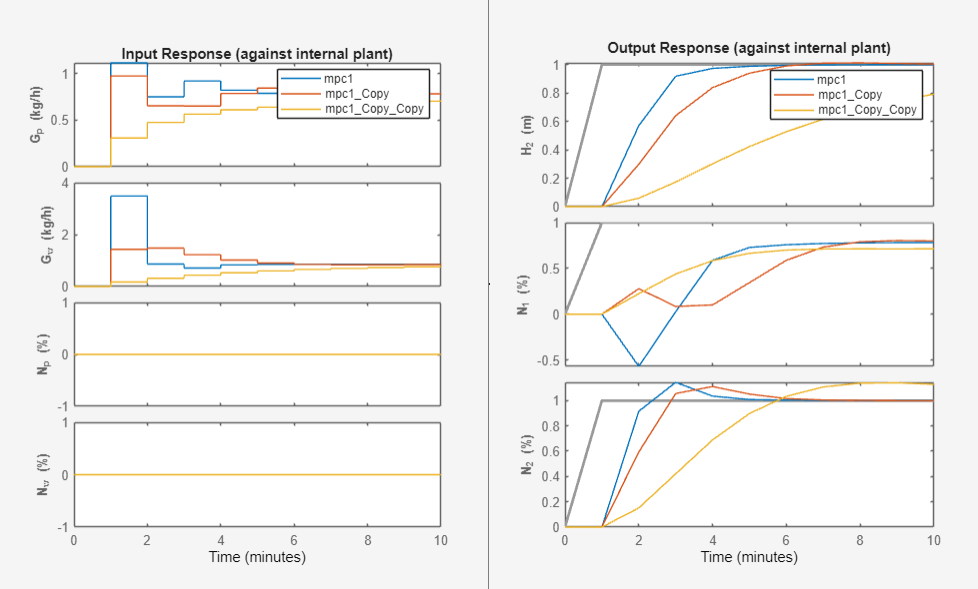

## Richiesta 6

Imposta il tempo di simulazione a 30 minuti. Come si può osservare una risposta al gradino unitario di $H_2$?

### Scelta del tempo di simulazione

Per modificare la durata della simulazione è necessario modificare il corrispettivo scenario.

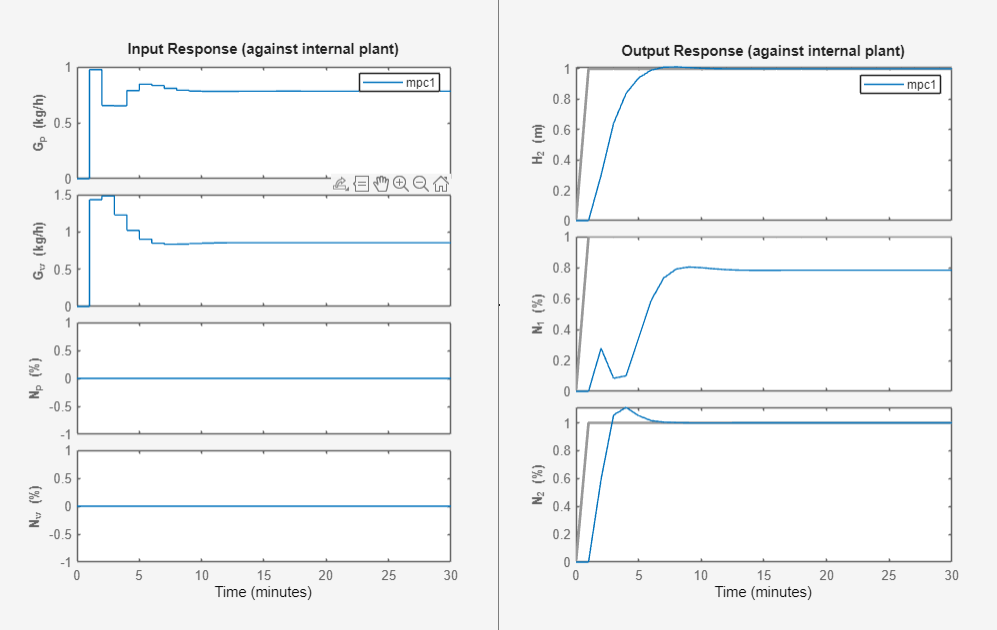

### Scelta del riferimento

Per osservare esclusivamente la risposta al gradino unitario di $H_2$ è necessario agire nuovamente sullo scenario e fare in modo che solo il riferimento di $H_2$ sia un gradino, mentre gli altri costanti.

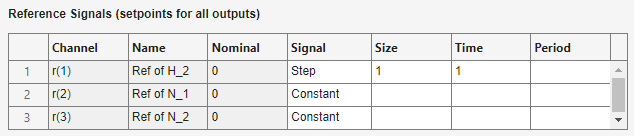

Avendo modificato i riferimenti, si ottiene il risultato desiderato.

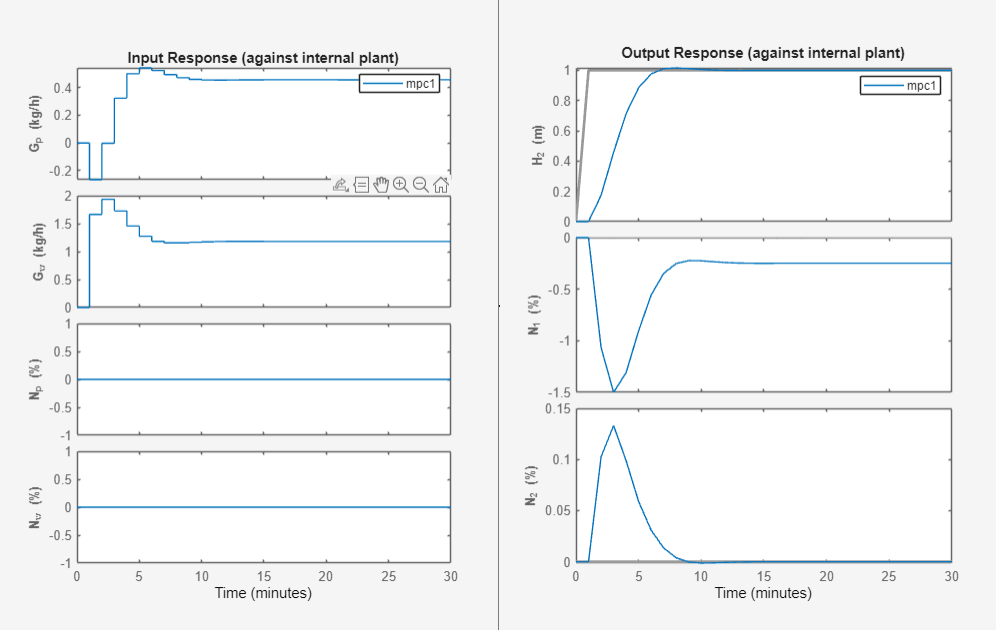

## Richiesta 7

Come specifica di progetto per il controllore, ti è richiesto di enfatizzare la consistenza del controllo sulla testata. Su quali parametri è necessario che tu intervenga?

### Scelta del riferimento

Per enfatizzare la consistenza del controllo sulla testata è necessario agire sulla variabile $N_2$ rappresentativa della densità del fluido. Conseguentemente si agisce nuovamente sullo scenario per impostare nuovamente un gradino unitario come riferimento.

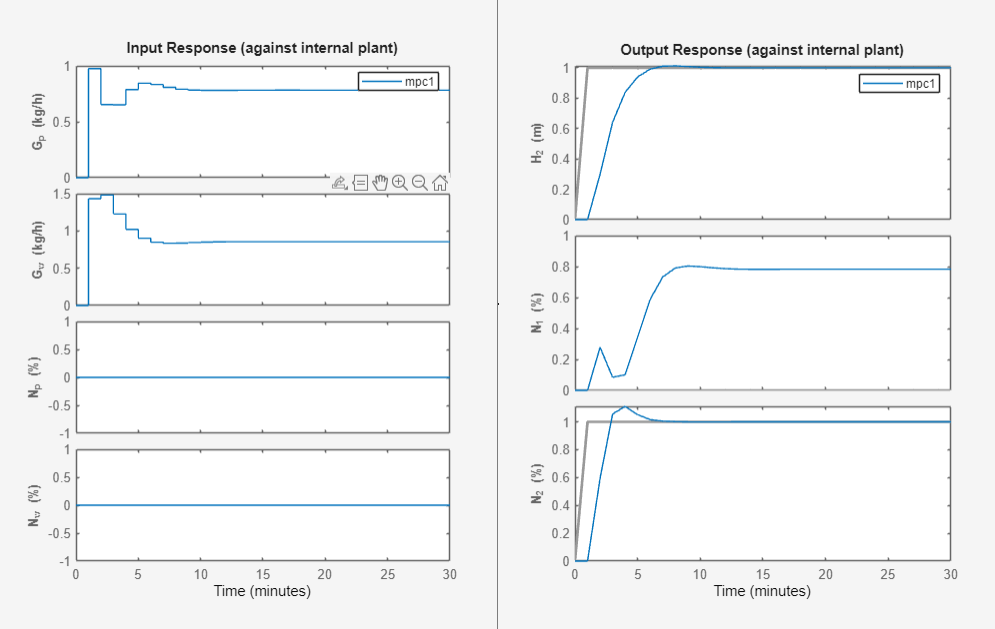

### Scelta dei pesi

Per fare in modo che il controllo sia più consistente si può incrementare ulteriormente il peso sulla variabile di uscita $N_2$:

- Un peso di 2 riduce leggermente l'overshoot

- Un peso di 4 riduce leggermente l'overshoot

- Un peso di 20 riduce in maniera significativa l'overshoot

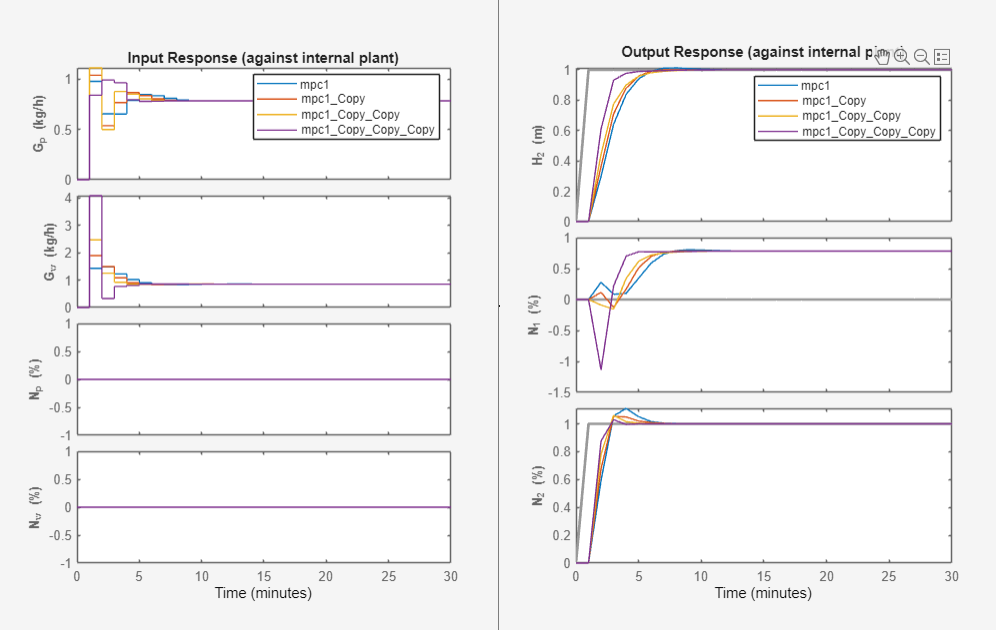

## Richiesta 8

Come si comporta il sistema in presenza di disturbi misurabili? E come in presenza in disturbi non misurabili?

### Analisi per disturbi misurabili

Per fare in modo che il disturbo misurabile abbia effetto sul sistema, è necessario modificare lo scenario specificando un riferimento a gradino, a partire dal minuto 5, per la variabile $N_p$.

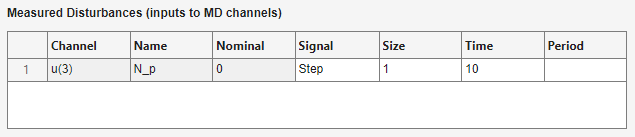

Si osserva la comparsa di un leggerissimo picco sull'uscita $N_1$ in corrispondenza del punto di applicazione del disturbo. A prescindere dal fatto che l'entità sia quasi impercettibile, è opportuno ricordare che su tale uscita non si ha alcuna specifica dunque può essere ignorata.

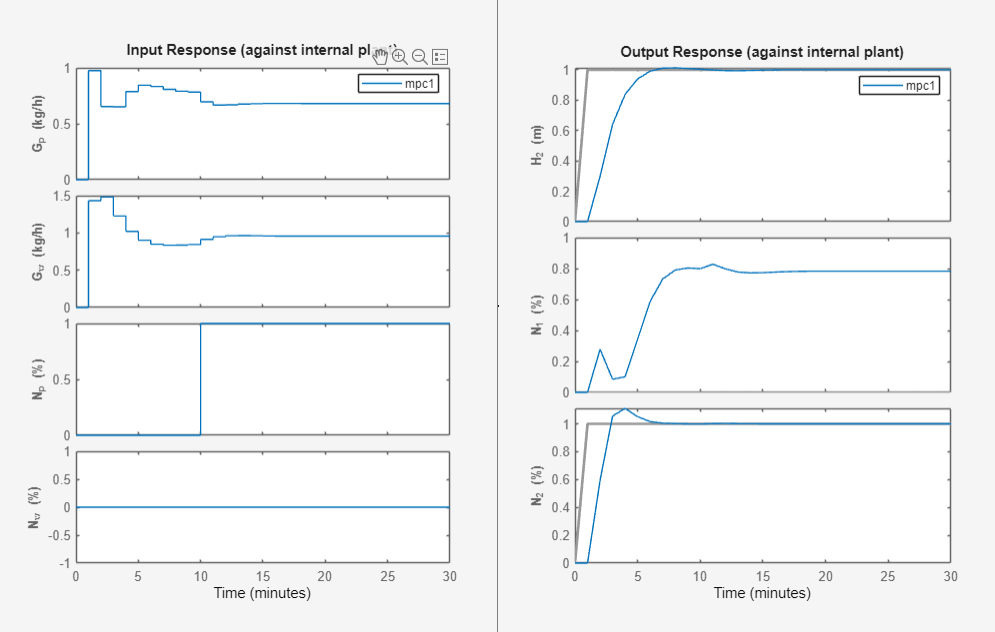

Si può concludere che un disturbo misurabile $N_p$ a gradino non influenza negativamente il controllore.

### Analisi per disturbi non misurabili

Per fare in modo che il disturbo non misurabile abbia effetto sul sistema, è necessario modificare lo scenario specificando un riferimento a gradino, a partire dal minuto 5, per la variabile $N_w$.

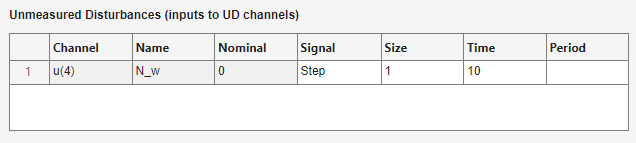

Si osserva la comparsa di un picco più importante su tutte le uscite in corrispondenza del punto di applicazione del disturbo, una situazione del tutto diversa rispetto al caso precedente. Tuttavia, il controllore è in grado di reagire e di assicurare un errore a regime nullo.

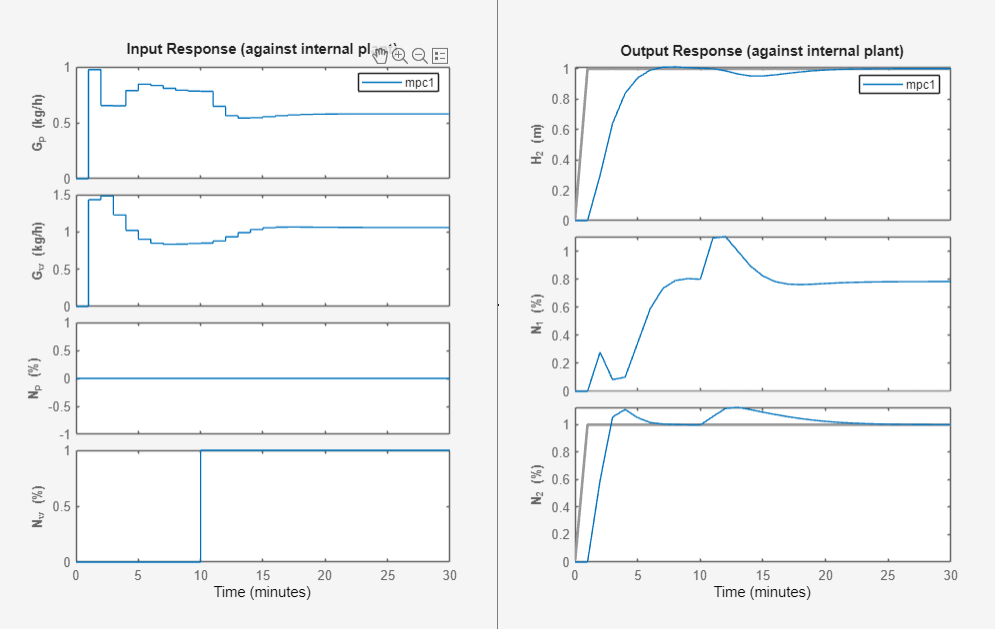

Si può concludere che un disturbo non misurabile $N_w$ a gradino mette in difficoltà il controllore, ma non degrada il comportamento a regime.

Diverse sono le considerazioni se si considera un disturbo non misurabile $N_w$ con andamento gaussiano. La prima uscita si mantiene tutto sommato stabile, mentre le restanti due assumono un comportamento insoddisfacente